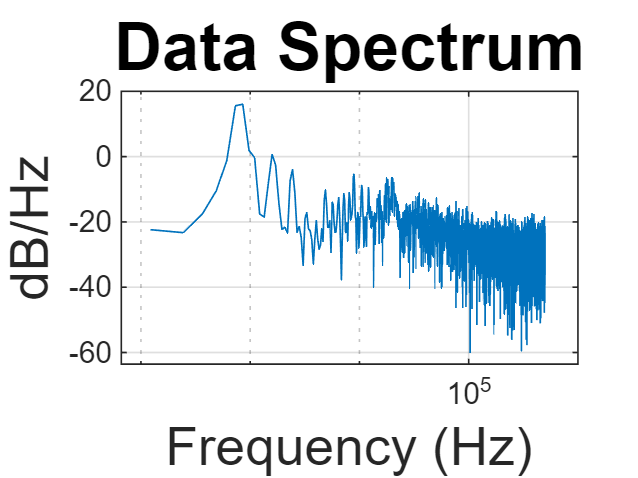

@Freq = 1000.000, SNR = 6.023 dB, SNDR = -18.074 dB, SFDR = 23.316 dB, HD2 = 23.316 and HD3 = 28.121


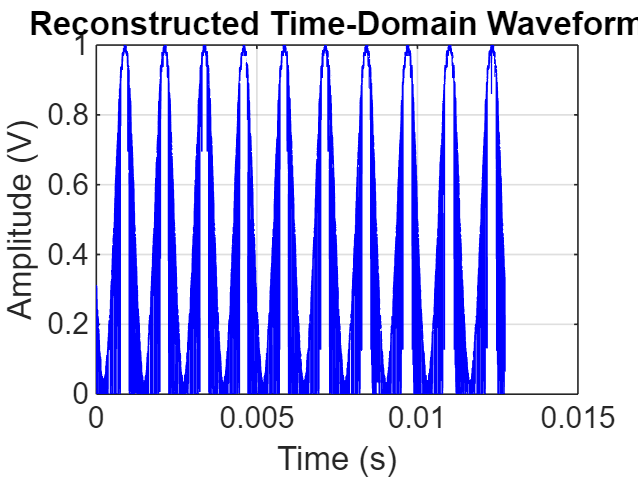

clearvars
freq_array = readtable('./ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/freq_array.csv');
freq_array = table2array(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'.0Hz_.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == 1)+1;
    time_diff = diff(rising_edge_indices);
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 10));
    % data_NewDec = data_NewDec(1:5000);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=2^floor(log2(length(data_NewDec)));
    % sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('BigSet.mat', 'BigSet');

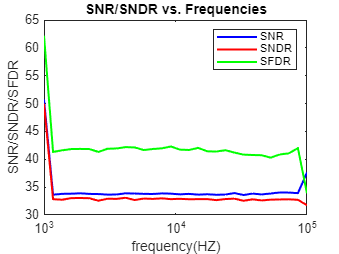

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

clearvars
load('./ADC_Data/CML-Data/12-2-EthanTB-Board4_SEDE-Freq_1k_250k-SIN_1000mV-CLK_1MHz_Duty50%/zhihao_100k_42_24.mat')
binary = char(filteredData);
DEC = binary(:,2:10);
DEC_New = bin2dec(DEC);

% Fs=1e6;
% num_segments=1;
% f_signal = 100e3;
% f_s = Fs;
% BW =Fs/2;
% sample_size=2^floor(log2(length(DEC_New)));
% % sample_size=length(data_NewDec);
% periodogram_length = sample_size / num_segments;
% fbin = f_s / periodogram_length;
% plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
% [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
%     plot_periodogram_SFDR(DEC_New, periodogram_length, num_segments, f_signal, ...
%     f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
% fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
% set(gcf,'color','w')
% BigSet(i,2) = SNR;
% BigSet(i,3) = SNDR;
% BigSet(i,4) = SFDR;

fs = 1e6;                 % Sampling rate in Hz
N = length(DEC_New);                  % Number of samples
bit_depth = 9;            % ADC bit resolution
V_min = 0;              % Minimum input voltage
V_max = 1;               % Maximum input voltage

% Map codes to voltage
voltages = ((DEC_New / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;

% Create time axis
t = (0:N-1) / fs;

% Plot the reconstructed waveform
figure;
plot(t, voltages, 'b');
title('Reconstructed Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;